clear;

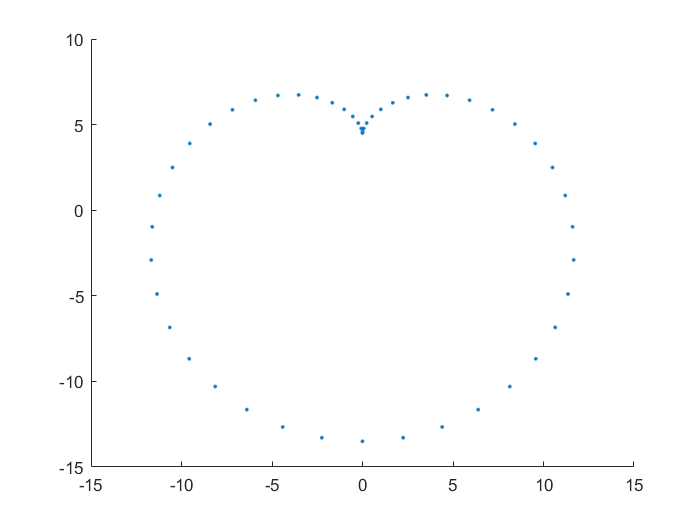

count = 50;
a = 9;
theta = 0:(2*pi/count):2*pi;
theta(end)=[];%抹去重复点
X = a*cos(theta')-cos(2*theta')*a/2;
Y = a*sin(theta')-sin(2*theta')*a/2;
Points = [Y,X];
Xn = 2.*X+a-a.*X./sqrt(X.^2+Y.^2);
Yn = 2*Y-a.*Y./sqrt(X.^2+Y.^2);
Normals = [Yn,Xn];
for i=1:length(theta)
    Normals(i,:)=Normals(i,:)./sum(Normals(i,:).^2);
end
% Normals(1,:)=[0 0];
% Normals(41,:)=[0 0];
scatter(Points(:,1),Points(:,2),'.');

n = length(theta);

k = 6*ones(n,1);
s = -0.5;
% 生成kd树
kdtree = KDTreeSearcher(Points);
boxlength=norm(min(Points)-max(Points));
% 计算各点支撑半径
SupportSizes = zeros(n,1);

distlist=SupportSizes;
mindist=distlist;
for i=1:n
    [indices,dists] = knnsearch(kdtree, Points(i,:), 'K', k(i));
    SupportSizes(i) = max(dists);
    mindist(i)=(dists(2));
    distlist(i)=(sum(dists)/k(i))/SupportSizes(i);
end
maxSupportSize = max(SupportSizes);
% 生成局部坐标系，各点二次曲线
[Bases,Hparas,Err] = CalHParas(Points,Normals,k,kdtree);





for i=1:n
    Err(i)=sqrt(CalErr(Points(i,1),Points(i,2),Points,Bases,Hparas, ...
        kdtree,maxSupportSize,SupportSizes,SupportSizes(i)));
end






% 设置拟合系数
ApproxArgs = zeros(n,1);
meanerr=mean(Err);
maxerr=max(Err);
minerr=min(Err);

aa=zeros(n,1);
mindist=mindist./SupportSizes;



x=min(Points(:,1));xx=max(Points(:,1));
y=min(Points(:,2));yy=max(Points(:,2));
boxlength=sqrt((xx-x)^2+(yy-y)^2);
[d,dn]=CalSumd(Points,x,xx,y,yy);
d=d/dn;
c=2*d/boxlength;
x=zeros(n,1);
for i=1:n
    ApproxArgs(i) =c;

%     indices(1)=[];
    if(Err(i)-meanerr>1e-7)
        x(i)=(Err(i)-meanerr)/(maxerr-minerr);
        ApproxArgs(i)=c/(1+x(i));
    elseif(Err(i)-meanerr<-1e-7)
        x(i)=(Err(i)-meanerr)/(maxerr-minerr);
        ApproxArgs(i)=c*(1-x(i));
    end


%     ApproxArgs(i) = c;
end



%  
% ApproxArgs([26]) = 0;
% ApproxArgs([27,25]) = 0.01;
% ApproxArgs([24,28])=0.7;
% 0;
% ApproxArgs([1]) = 0;
% ApproxArgs([2,end]) = 0;
% ApproxArgs([3,end-1]) = 0.01;
% ApproxArgs([4,end-2]) = 1;
% ApproxArgs([5,end-3]) = 0.1;
% ApproxArgs(41) = 0;
% 计算C值
C = zeros(n,1);
for i=1:n
    [indices,dists] = rangesearch(kdtree, Points(i,:), maxSupportSize);
    indices = indices{1};
    dists = dists{1};
    valsum = 0;
    rbfsum = 0;
    H = Calh(Points(i,1),Points(i,2),Points(indices,:),Bases(indices,:),Hparas(indices));
    for j=1:length(indices)
        if dists(j)>=SupportSizes(indices(j))
            continue
        end
        %Wendland part
        value = rbf_wend(dists(j)/SupportSizes(indices(j)));
        %shepard part
%         value = rbf_shp(dists(j)/SupportSizes(indices(j)));
%         if(value==inf)
%             valsum=H(j);
%             rbfsum=1;
%             break;
%         end
        %Our method
        if dists(j)<1e-7 && ApproxArgs(indices(j))<1e-7 
            valsum = C(indices(j))+H(j);
            rbfsum = 1;
            break;
        end
        value = rbf(dists(j)/SupportSizes(indices(j)),ApproxArgs(indices(j)),s);
% %         
        valsum = valsum - H(j)*value;
        rbfsum = rbfsum + value;
    end
    C(i) = valsum/rbfsum;
end

% % 画隐曲线
f = @(x,y)(CalRBFV(x,y,kdtree,Points,Bases,Hparas, ...
    maxSupportSize,SupportSizes,ApproxArgs,s,C,1));
area = [-12,12,-14,7.5];
% fp = fimplicit(f, area);
% 
% hold on;
% scatter(Points(:,1),Points(:,2),'*');
% hold off;

% %样本点误差
% F=zeros(n,1);
% for j=1:n
%     F(j)=f(Points(j,1),Points(j,2));
% end
% e1=max(abs(F))

%插值误差
F1=zeros(length(theta),1);
for j=1:length(theta)
    F1(j)=f(Points(j,1),Points(j,2));
end
[Maxe1]=max(abs(F1))

Maxe1 = 0.0039

Meane1=mean(abs(F1))

Meane1 = 4.8294e-04

%测试点误差
res = 2000;
theta = 0:(2*pi/res):2*pi;
X = a*cos(theta')-cos(2*theta')*a/2;
Y = a*sin(theta')-sin(2*theta')*a/2;
F=zeros(length(theta),1);
respoints = [Y,X];
for j=1:length(theta)
    F(j)=f(respoints(j,1),respoints(j,2));
end
Maxe2=max(abs(F))

Maxe2 = 0.0064

Meane2=mean(abs(F))

Meane2 = 8.0253e-04

% % %A series test
% count = 20:10:100;
% theta=cell(length(count),1);PPoints=theta;NNormals=PPoints;
% nn=PPoints;
% for i=1:length(count)
%     theta{i} = 0:(2*pi/count(i)):2*pi;
%     X = a*cos(theta{i}')-cos(2*theta{i}')*a/2-a/2;
%     Y = a*sin(theta{i}')-sin(2*theta{i}')*a/2;
%     PPoints{i} = [Y,X];
%     Xn = 2.*X+a-a.*X./sqrt(X.^2+Y.^2);
%     Yn = 2*Y-a.*Y./sqrt(X.^2+Y.^2);
%     Normals = [Yn,Xn];
%     Normals(1,:)=[0 0];
%     Normals(end,:)=[0 0];
%     NNormals{i} = Normals;
%     nn{i} = length(theta{i});
% end
% 
% s=-0.5;
% maxApproxArg=1;
% minApproxArg=0.3;
% 
% Maxtesterror=zeros(length(count),1);
% Meantesterror=zeros(length(count),1);
% 
% for j=1:length(count)
%    Points=PPoints{j};n=nn{j};
%     Normals=NNormals{j};
%     kdtree = KDTreeSearcher(Points);
%     k = 5*ones(n,1);
%     SupportSizes = zeros(n,1);
%     distlist=SupportSizes;
%     for i=1:n
%         [indices,dists] = knnsearch(kdtree, Points(i,:), 'K', k(i));
%         SupportSizes(i) = max(dists);
%         distlist(i)=dists(2);
%     end
%     maxSupportSize = max(SupportSizes);
%     % 生成局部坐标系，各点二次曲线
%     [Bases,Hparas,Err] = CalHParas(Points,Normals,k,kdtree);
%     ApproxArgs = zeros(n,1);
%     maxerr=max(Err);
%     minerr=min(Err);
%     Err=(Err-minerr)/(maxerr-minerr);
%     meanerr=mean(Err);
%     maxd=max(distlist);
%     mind=min(distlist);
%     distlist=(distlist-mind)/(maxd-mind);
%     var=sum((Err-meanerr).^2)/n;
%     meand=mean(distlist);
%     vard=sum((distlist-meand).^2)/n;
%     for i=1:n
%         ApproxArgs(i) = 1;
%         if((distlist(i)-meand)^2>3*vard)
%             x=sqrt(((distlist(i)-meand)^2)/(vard));
%             if((distlist(i)-meand)<0)
%                 ApproxArgs(i)=ApproxArgs(i)+x*meand;
%             else
%                 ApproxArgs(i)=ApproxArgs(i)-1/x*meand;
%             end
%         elseif((Err(i)-meanerr)^2>3*var)
%             x=sqrt((Err(i)-meanerr)^2/((var)));
%             if(Err(i)-meanerr>0)
%                 ApproxArgs(i)=ApproxArgs(i)-(1/x)*meanerr;
%             else
%                 ApproxArgs(i)=ApproxArgs(i)+(x)*meanerr;
%             end
%         end
%     end
%     %%%计算对应的各个参数
%     C = zeros(n,1);
%     for i=1:n
%         [indices,dists] = rangesearch(kdtree, Points(i,:), maxSupportSize);
%         indices = indices{1};
%         dists = dists{1};
%         valsum = 0;
%         rbfsum = 0;
%         H = Calh(Points(i,1),Points(i,2),Points(indices,:),Bases(indices,:),Hparas(indices));
%         for j1=1:length(indices)
%             if dists(j1)>=SupportSizes(indices(j1))
%                 continue
%             end
%             %Wendland part
% %           value = rbf_wend(dists(j)/SupportSizes(indices(j)));
%             %shepard part
% %           value = rbf_shp(dists(j)/SupportSizes(indices(j)));
% %           if(value==inf)
% %               valsum=H(j);
% %               rbfsum=1;
% %               break;
% %           end
%             %Our method
%             if dists(j1)<1e-7 && ApproxArgs(indices(j1))<1e-7 
%                 valsum = C(indices(j1))+H(j1);
%                 rbfsum = 1;
%                 break;
%             end
%             value = rbf(dists(j1)/SupportSizes(indices(j1)),ApproxArgs(indices(j1)),s);
%         
%             valsum = valsum - H(j1)*value;
%             rbfsum = rbfsum + value;
%         end
%         C(i) = valsum/rbfsum;
%     end
%     f = @(x,y)(CalRBFV(x,y,kdtree,Points,Bases,Hparas,maxSupportSize,SupportSizes,ApproxArgs,s,C,1));
%     res = 1000;
%     restheta = 0:(2*pi/res):2*pi;
%     X = a*cos(restheta')-cos(2*restheta')*a/2-a/2;
%     Y = a*sin(restheta')-sin(2*restheta')*a/2;
%     respoints=[Y,X];
%     F=zeros(length(restheta),1);
%     for i=1:length(restheta)
%         F(i)=f(respoints(i,1),respoints(i,2));
%     end
%     error2=abs(F);
%     Maxtesterror(j)=max(error2);
%     Meantesterror(j)=mean(error2);
% end

% Maxtesterror_W=zeros(length(count),1);
% Meantesterror_W=zeros(length(count),1);
% 
% for j=1:length(count)
%    Points=PPoints{j};n=nn{j};
%     Normals=NNormals{j};
%     kdtree = KDTreeSearcher(Points);
%     k = 5*ones(n,1);
%     for i=1:n
%         [indices,dists] = knnsearch(kdtree, Points(i,:), 'K', k(i));
%         SupportSizes(i) = max(dists);
%     end
%     maxSupportSize = max(SupportSizes);
%     % 生成局部坐标系，各点二次曲线
%     [Bases,Hparas,Err] = CalHParas(Points,Normals,k,kdtree);
%     %对应的各个参数
%     C = zeros(n,1);
%     for i=1:n
%         [indices,dists] = rangesearch(kdtree, Points(i,:), maxSupportSize);
%         indices = indices{1};
%         dists = dists{1};
%         valsum = 0;
%         rbfsum = 0;
%         H = Calh(Points(i,1),Points(i,2),Points(indices,:),Bases(indices,:),Hparas(indices));
%         for j1=1:length(indices)
%             if dists(j1)>=SupportSizes(indices(j1))
%                 continue
%             end
%             %Wendland part
%           value = rbf_wend(dists(j1)/SupportSizes(indices(j1)));
%             %shepard part
% %           value = rbf_shp(dists(j)/SupportSizes(indices(j)));
% %           if(value==inf)
% %               valsum=H(j);
% %               rbfsum=1;
% %               break;
% %           end
%             %Our method
% %             if dists(j1)<1e-7 && ApproxArgs(indices(j1))<1e-7 
% %                 valsum = C(indices(j1))+H(j1);
% %                 rbfsum = 1;
% %                 break;
% %             end
% %             value = rbf(dists(j1)/SupportSizes(indices(j1)),ApproxArgs(indices(j1)),s);
% %         
%             valsum = valsum - H(j1)*value;
%             rbfsum = rbfsum + value;
%         end
%         C(i) = valsum/rbfsum;
%     end
%     f = @(x,y)(CalRBFV(x,y,kdtree,Points,Bases,Hparas,maxSupportSize,SupportSizes,ApproxArgs,s,C,2));
%     res = 1000;
%     restheta = 0:(2*pi/res):2*pi;
%     X = a*cos(restheta')-cos(2*restheta')*a/2-a/2;
%     Y = a*sin(restheta')-sin(2*restheta')*a/2;
%     respoints=[Y,X];
%     F=zeros(length(restheta),1);
%     for i=1:length(restheta)
%         F(i)=f(respoints(i,1),respoints(i,2));
%     end
%     error2=abs(F);
%     Maxtesterror_W(j)=max(error2);
%     Meantesterror_W(j)=mean(error2);
% end

% figure;
% plot(count,-log10(Maxtesterror),count,-log10(Meantesterror), '*-','linewidth', 2);
% hold on
% plot(count,-log10(Maxtesterror_W),count,-log10(Meantesterror_W), 'o-','linewidth', 2);
% hold off;

%A series test
alpha=0:0.1:3;
count = 50;
a = 9;
theta = 0:(2*pi/count):2*pi;
% theta(41)=[];theta(1)=[];
X = a*cos(theta')-cos(2*theta')*a/2;
Y = a*sin(theta')-sin(2*theta')*a/2;
Points = [Y,X];
Xn = 2.*X+a-a.*X./sqrt(X.^2+Y.^2);
Yn = 2*Y-a.*Y./sqrt(X.^2+Y.^2);
Normals = [Yn,Xn];
scatter(Points(:,1),Points(:,2),'.');

n = length(theta);

s=-0.5;

Maxtesterror=zeros(length(alpha),1);
Meantesterror=zeros(length(alpha),1);
MaxIerror=zeros(length(a),1);
MeanIerror=zeros(length(a),1);

for j=1:length(alpha)
    kdtree = KDTreeSearcher(Points);
    k = 6*ones(n,1);
    SupportSizes = zeros(n,1);
    distlist=zeros(n,1);
    mindist=distlist;
    for i=1:n
        [indices,dists] = knnsearch(kdtree, Points(i,:), 'K', k(i));
        SupportSizes(i) = max(dists);
        mindist(i)=dists(2);
        distlist(i)=(sum(dists)/k(i))/SupportSizes(i);
    end
    maxSupportSize = max(SupportSizes);
    ApproxArgs = zeros(n,1);
    % 生成局部坐标系，各点二次曲线
    [Bases,Hparas,Err] = CalHParas(Points,Normals,k,kdtree);
    meanerr=mean(Err);
    var=sum((Err-meanerr).^2)/n;
    meand=mean(distlist);
    vard=sum((distlist-meand).^2)/n;
    meanmd=mean(mindist);
    varmd=sum((mindist-meanmd).^2)/n;
    %%%计算对应的各个参数
    c=alpha(j);
    for i1=1:n
        ApproxArgs(i1) = c;
    end
    %%%计算对应的各个参数
    C = zeros(n,1);
    for i=1:n
        [indices,dists] = rangesearch(kdtree, Points(i,:), maxSupportSize);
        indices = indices{1};
        dists = dists{1};
        valsum = 0;
        rbfsum = 0;
        H = Calh(Points(i,1),Points(i,2),Points(indices,:),Bases(indices,:),Hparas(indices));
        for j1=1:length(indices)
            if dists(j1)>=SupportSizes(indices(j1))
                continue
            end
            %Wendland part
%           value = rbf_wend(dists(j)/SupportSizes(indices(j)));
            %shepard part
%           value = rbf_shp(dists(j)/SupportSizes(indices(j)));
%           if(value==inf)
%               valsum=H(j);
%               rbfsum=1;
%               break;
%           end
            %Our method
            if dists(j1)<1e-7 && ApproxArgs(indices(j1))<1e-7 
                valsum = C(indices(j1))+H(j1);
                rbfsum = 1;
                break;
            end
            value = rbf(dists(j1)/SupportSizes(indices(j1)),ApproxArgs(indices(j1)),s);
        
            valsum = valsum - H(j1)*value;
            rbfsum = rbfsum + value;
        end
        C(i) = valsum/rbfsum;
    end
    f = @(x,y)(CalRBFV(x,y,kdtree,Points,Bases,Hparas,maxSupportSize,SupportSizes,ApproxArgs,s,C,1));
    res = 1000;
    F=zeros(length(theta),1);
    for i=1:length(theta)
        F(i)=f(Points(i,1),Points(i,2));
    end
    error1=abs(F);
    restheta = 0:(2*pi/res):2*pi;
    X = a*cos(restheta')-cos(2*restheta')*a/2;
    Y = a*sin(restheta')-sin(2*restheta')*a/2;
    respoints=[Y,X];
    F=zeros(length(restheta),1);
    for i=1:length(restheta)
        F(i)=f(respoints(i,1),respoints(i,2));
    end
    error2=abs(F);
    Maxtesterror(j)=log10(max(error2));
    Meantesterror(j)=log10(mean(error2));
    MaxIerror(j)=log10(max(error1));
    MeanIerror(j)=log10(mean(error1));
end

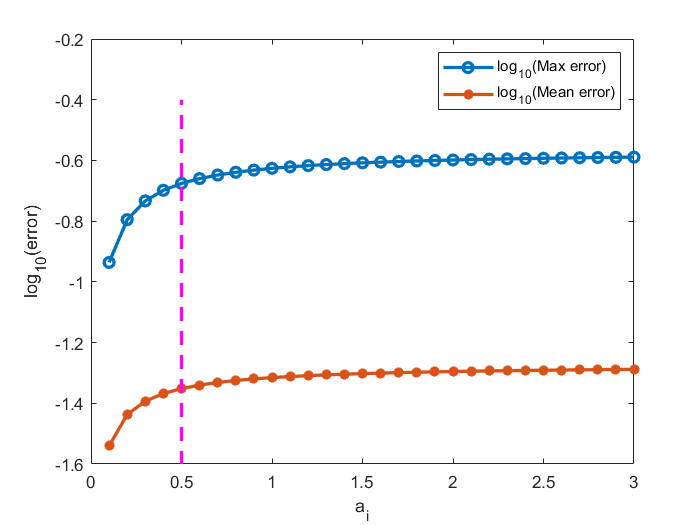

plot(alpha,MaxIerror,'-o',alpha,MeanIerror, '-*','linewidth', 2);
hold on
plot([0.5,0.5],ylim,'m--','linewidth', 2);
xlabel('a_i')
ylabel('log_{10}(error)')
legend('log_{10}(Max error)','log_{10}(Mean error)')
hold off

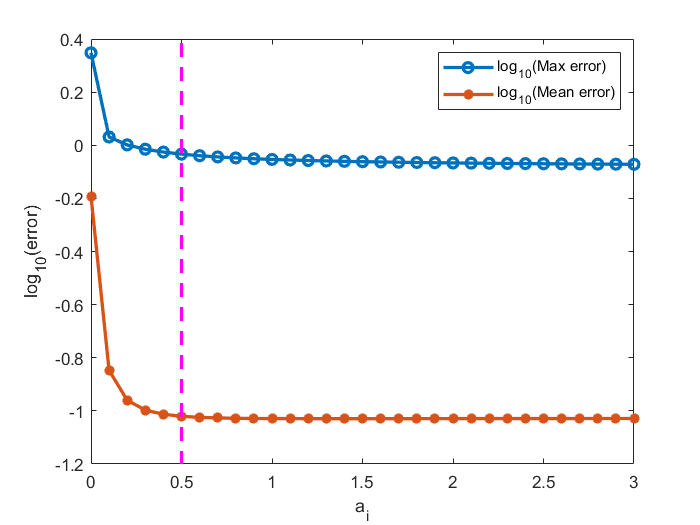

plot(alpha,Maxtesterror,'-o',alpha,Meantesterror, '-*','linewidth', 2);
hold on
plot([0.5,0.5],ylim,'m--','linewidth', 2);
xlabel('a_i')
ylabel('log_{10}(error)')
legend('log_{10}(Max error)','log_{10}(Mean error)')
hold off